# **Homework #7 Dit Dejphachon**

## **8.2.2. **

(a) Assume the coefficient of shear viscosity in air is independent of pressure and is the dominant  loss mechanism. What is $\tau_S$ in air at 20°C and 0.1 atm? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.2.2.     a)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.2.2.     a)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



rho_0 = 0.119;
c = 343;
eta = 1.85e-5;

gamma = 1.402;   % heat capacity ratio (dimensionless) - Appendix A10 in Kinsler
kappa = 0.025822;% thermal conductivity (W/m*K) - Appendix A10 in Kinsler
c_p = 1.0049e3;  % specific heat (J/kg*K) - Appendix A10 in Kinsler

eta_B = (gamma - 1).*kappa./c_p

eta_B = 1.0330e-05

tau_s = ((4/3)*eta + eta_B)/(rho_0*c^2)

tau_s = 2.4997e-09

(b) At what frequency will ${\omega \tau }_S =1$? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.2.2.     b)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.2.2.     b)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



f = 1/(2*pi*tau_s)

f = 6.3669e+07

f = f*(1/(2*pi)) 

f = 1.0133e+07

(c)  Calculate $\alpha_S$ and $c_p$ at this frequency. 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.2.2.     c)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.2.2.     c)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



omega = 1/(tau_s)

omega = 4.0005e+08


omegaTau_s = omega*tau_s

omegaTau_s = 1


alpha_s = (omega/c)*(1/sqrt(2))*((sqrt(1 + omegaTau_s^2) - 1)/(1 + (omegaTau_s)^2))^(0.5)

alpha_s = 3.7532e+05


c_p = c*sqrt(2)*((1 + (omegaTau_s)^2)/(sqrt(1 + omegaTau_s^2) + 1))^(0.5)

c_p = 441.5057

(d) What are they in air at 1.0 atm pressure at this same  frequency?

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.2.2.     d)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.2.2.     d)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



rho_0 = 1.21;
c = 343;
eta = 1.85e-5;

gamma = 1.402;   % heat capacity ratio (dimensionless) - Appendix A10 in Kinsler
kappa = 0.0263;% thermal conductivity (W/m*K) - Appendix A10 in Kinsler
c_p = 1.01e3;  % specific heat (J/kg*K) - Appendix A10 in Kinsler

eta_B = (gamma - 1).*kappa./c_p;
tau_s = ((4/3)*eta + eta_B)/(rho_0*c^2)

tau_s = 2.4681e-10


omegaTau_s = omega*tau_s

omegaTau_s = 0.0987


alpha_s = (omega/c)*(1/sqrt(2))*((sqrt(1 + omegaTau_s^2) - 1)/(1 + (omegaTau_s)^2))^(0.5)

alpha_s = 5.7230e+04


c_p = c*sqrt(2)*((1 + (omegaTau_s)^2)/(sqrt(1 + omegaTau_s^2) + 1))^(0.5)

c_p = 344.2496

## 8.6.1. From (8.6.14) find the frequency for which $\frac{\alpha_{M\;} }{k}$ is maximized

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%       HW#8.6.1.               %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%       HW#8.6.1.               %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



syms tau_M R C_i C_e omega pi

f = (0.5) * ((R*C_i)/(C_e*(C_e + R))) * ((omega*tau_M)/(1 + (omega*tau_M)^2))

$$f = \frac{C_{i}\,R\,\omega \,\tau_{M}}{2\,C_{e}\,\left(\omega^{2}\,{\tau_{M}}^{2}+1\right)\,\left(C_{e}+R\right)}$$

f2 = diff(f,omega)==0

$$f2 = \frac{C_{i}\,R\,\tau_{M}}{2\,C_{e}\,\left(\omega^{2}\,{\tau_{M}}^{2}+1\right)\,\left(C_{e}+R\right)}-\frac{C_{i}\,R\,\omega^{2}\,{\tau_{M}}^{3}}{C_{e}\,{\left(\omega^{2}\,{\tau_{M}}^{2}+1\right)}^{2}\,\left(C_{e}+R\right)}=0$$

extreme_points = solve(f2,omega)

$$extreme\_points = \left(\begin{array}{c} -\frac{1}{\tau_{M}}\\ \frac{1}{\tau_{M}} \end{array}\right)$$



f = (1/(2*pi))*extreme_points(2)

$$f = \frac{1}{2\,\pi \,\tau_{M}}$$


clear pi

## 8.6.4. 

A siren is to operate at ***500 Hz in air ***and at a small height above the ground. 

Assuming hemispherical divergence and no absorption by the ground, 

what is the ***absorption coefficient***  and 

what must be the ***acoustic output of the siren in watts*** if it is to produce an 

          ***  intensity level  of 60 dB ***

***            re 20 μPa ***

***            at a distance of 1000 ft ***

for each of the following conditions: 

(a) no  absorption by the air, 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.6.4.     a)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.6.4.     a)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



alpha_s = 0

alpha_s = 0

I = 10e-7

I = 1.0000e-06

(b) according to the classical absorption coefficient, 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.6.4.     b)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.6.4.     b)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



alpha_s = 7e-4

alpha_s = 7.0000e-04


R = 1000*0.3048;
I_B = I*exp(-2*(alpha_s/8.7)*R)

I_B = 9.5214e-07

(c) completely dry air,  and 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.6.4.     c)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.6.4.     c)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



alpha_s = (9.5e-2)

alpha_s = 0.0950


I_B = I*exp(-2*(alpha_s/8.7)*R)

I_B = 1.2856e-09

(d) air of very high relative humidity.

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.6.4.     d)       %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.6.4.     d)       %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



alpha_s = 8.5e-2

alpha_s = 0.0850

I_B = I*exp(-2*(alpha_s/8.7)*R)

I_B = 2.5906e-09

## 8.7.2. 

A 1 kHz plane wave traverses freshwater at 15°C. 

(a) In what distance will it be attenuated  by 10 dB? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.2.      a)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.2.      a)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



P_0 = 1;
x = 10000:10000:1000000000;
t=10;

f = 1000;       % Hz
omega = 2.*pi.*f; % angular frequency (rad/s)
rho_0 = 998;   % density of fluid (kg/m^3) - Appendix A10 in Kinsler
c = 1481;        % speed of sound (m/s) - Appendix A10 in Kinsler
k = omega./c;   % wave number
eta = 1.0e-3;  % shear viscosity coefficient (Pa*s) - Appendix A10 in Kinsler
gamma = 1.004;  % heat capacity ratio (dimensionless) - Appendix A10 in Kinsler
kappa = 0.603; % thermal conductivity (W/m*K) - Appendix A10 in Kinsler
c_p = 4.19e3;   % specific heat (J/kg*K) - Appendix A10 in Kinsler
Pr = eta.*c_p/kappa;

alpha_c_air = omega.^2./2./rho_0./c.^3.*(4/3.*eta + (gamma - 1).*kappa./c_p)

alpha_c_air = 8.1219e-09

p_air = abs(P_0.*exp(-alpha_c_air.*x).*exp(1j.*(omega.*t-k.*x)))

p_air =     0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9994    0.9993    0.9992    0.9991    0.9990    0.9989    0.9989    0.9988    0.9987    0.9986    0.9985    0.9985    0.9984    0.9983    0.9982    0.9981    0.9981    0.9980    0.9979    0.9978    0.9977    0.9976    0.9976    0.9975    0.9974    0.9973    0.9972    0.9972    0.9971    0.9970    0.9969    0.9968    0.9968    0.9967    0.9966    0.9965    0.9964    0.9964    0.9963    0.9962    0.9961    0.9960    0.9959


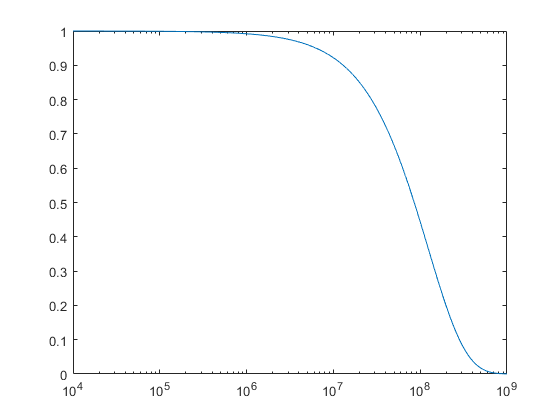

semilogx(x, p_air)


syms P_e
f1 = -10 == 20*log10(P_e/P_0)

$$f1 = -10=\frac{20\,\log\left(P_{e}\right)}{\log\left(10\right)}$$

vpa(solve(f1,P_e),3)

$$ans = 0.316$$

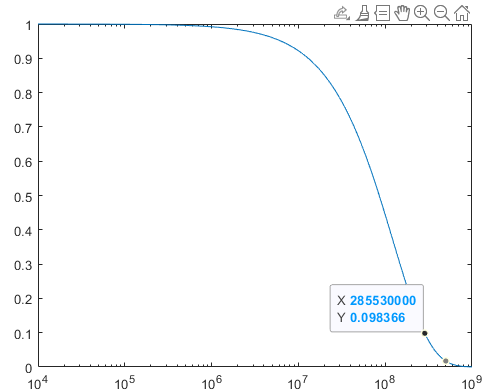

(b) Work the same problem for 20 kHz.

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.2.      b)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.2.      b)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



P_0 = 10;
x = 10000:10000:1000000000;

f = 20e3;       % Hz
omega = 2.*pi.*f; % angular frequency (rad/s)
rho_0 = 998;   % density of fluid (kg/m^3) - Appendix A10 in Kinsler
c = 1481;        % speed of sound (m/s) - Appendix A10 in Kinsler
k = omega./c;   % wave number
eta = 1.0e-3;  % shear viscosity coefficient (Pa*s) - Appendix A10 in Kinsler
gamma = 1.004;  % heat capacity ratio (dimensionless) - Appendix A10 in Kinsler
kappa = 0.603; % thermal conductivity (W/m*K) - Appendix A10 in Kinsler
c_p = 4.19e3;   % specific heat (J/kg*K) - Appendix A10 in Kinsler

alpha_c_air = omega.^2./2./rho_0./c.^3.*(4/3.*eta + (gamma - 1).*kappa./c_p)

alpha_c_air = 3.2488e-06

p_air = abs(P_0.*exp(-alpha_c_air.*x).*exp(1j.*(omega.*t-k.*x)))

p_air =     9.6803    9.3709    9.0714    8.7814    8.5007    8.2289    7.9659    7.7113    7.4648    7.2262    6.9952    6.7716    6.5551    6.3456    6.1427    5.9464    5.7563    5.5723    5.3942    5.2217    5.0548    4.8932    4.7368    4.5854    4.4388    4.2969    4.1596    4.0266    3.8979    3.7733    3.6527    3.5359    3.4229    3.3135    3.2076    3.1050    3.0058    2.9097    2.8167    2.7266    2.6395    2.5551    2.4734    2.3944    2.3178    2.2437    2.1720    2.1026    2.0354    1.9703


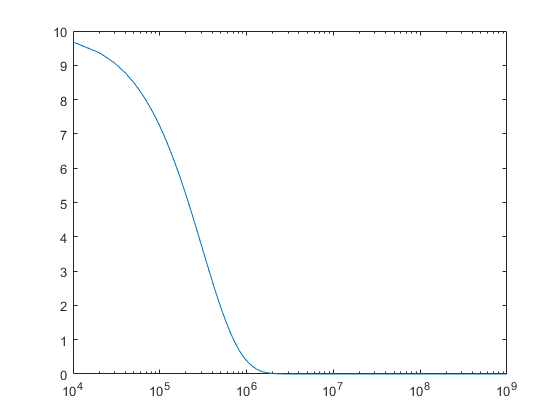

semilogx(x, p_air)

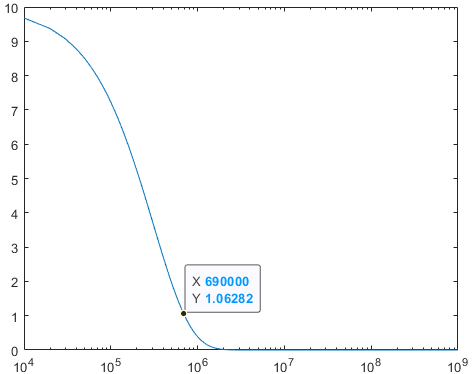 

(c) What are the corresponding distances in  seawater at 15°C? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.2.      c)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.2.      c)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



P_0 = 10;
x = 10000:10000:1000000000;

f = 1000;        % Hz
omega = 2.*pi.*f; % angular frequency (rad/s)
rho_0 = 1026;    % density of fluid (kg/m^3) - Appendix A10 in Kinsler
c = 1500;        % speed of sound (m/s) - Appendix A10 in Kinsler
k = omega./c;    % wave number
eta = 1.07e-3;   % shear viscosity coefficient (Pa*s) - Appendix A10 in Kinsler
gamma = 1.01;    % heat capacity ratio (dimensionless) - Appendix A10 in Kinsler
kappa = 0.603;   % thermal conductivity (W/m*K) - Appendix A10 in Kinsler
c_p = 4.19e3;    % specific heat (J/kg*K) - Appendix A10 in Kinsler

alpha_c_air = omega.^2./2./rho_0./c.^3.*(4/3.*eta + (gamma - 1).*kappa./c_p)

alpha_c_air = 8.1408e-09

p_air = abs(P_0.*exp(-alpha_c_air.*x).*exp(1j.*(omega.*t-k.*x)))

p_air =     9.9992    9.9984    9.9976    9.9967    9.9959    9.9951    9.9943    9.9935    9.9927    9.9919    9.9910    9.9902    9.9894    9.9886    9.9878    9.9870    9.9862    9.9854    9.9845    9.9837    9.9829    9.9821    9.9813    9.9805    9.9797    9.9789    9.9780    9.9772    9.9764    9.9756    9.9748    9.9740    9.9732    9.9724    9.9715    9.9707    9.9699    9.9691    9.9683    9.9675    9.9667    9.9659    9.9651    9.9642    9.9634    9.9626    9.9618    9.9610    9.9602    9.9594


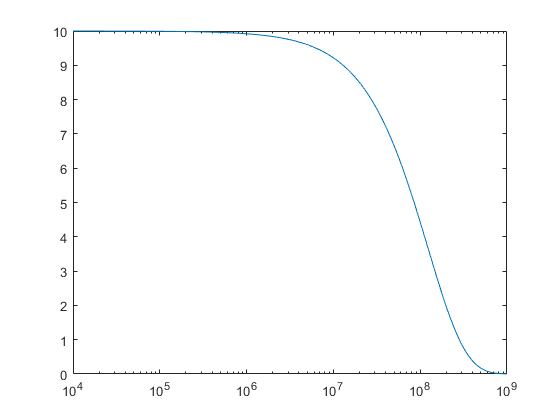

semilogx(x, p_air)

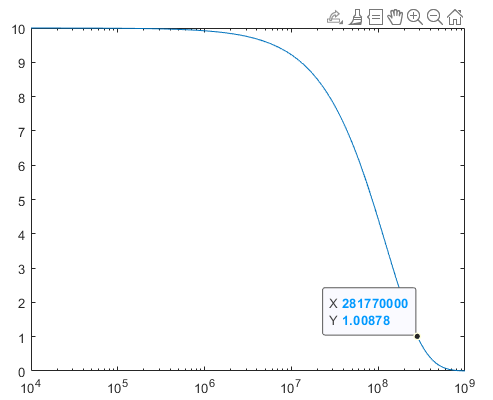

(d) In dry air at 20°C? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.2.      d)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.2.      d)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



P_0 = 10;
x = 10000:10000:1000000000;

%Air
f = 1000;       % Hz
omega = 2.*pi.*f;% angular frequency (rad/s)
rho_0 = 1.21;   % density of fluid (kg/m^3) - Appendix A10 in Kinsler
c = 343;        % speed of sound (m/s) - Appendix A10 in Kinsler
k = omega./c;   % wave number
eta = 1.85e-5;  % shear viscosity coefficient (Pa*s) - Appendix A10 in Kinsler
gamma = 1.402;  % heat capacity ratio (dimensionless) - Appendix A10 in Kinsler
kappa = 0.0263; % thermal conductivity (W/m*K) - Appendix A10 in Kinsler
c_p = 1.01e3;   % specific heat (J/kg*K) - Appendix A10 in Kinsler
Pr = eta.*c_p/kappa;

alpha_c_air = omega.^2./2./rho_0./c.^3.*(4/3.*eta + (gamma - 1).*kappa./c_p)

alpha_c_air = 1.4204e-05

p_air = abs(P_0.*exp(-alpha_c_air.*x).*exp(1j.*(omega.*t-k.*x)))

p_air =     8.6759    7.5271    6.5305    5.6658    4.9156    4.2647    3.7000    3.2101    2.7850    2.4163    2.0963    1.8188    1.5779    1.3690    1.1877    1.0305    0.8940    0.7757    0.6729    0.5838    0.5065    0.4395    0.3813    0.3308    0.2870    0.2490    0.2160    0.1874    0.1626    0.1411    0.1224    0.1062    0.0921    0.0799    0.0693    0.0602    0.0522    0.0453    0.0393    0.0341    0.0296    0.0257    0.0223    0.0193    0.0168    0.0145    0.0126    0.0109    0.0095    0.0082


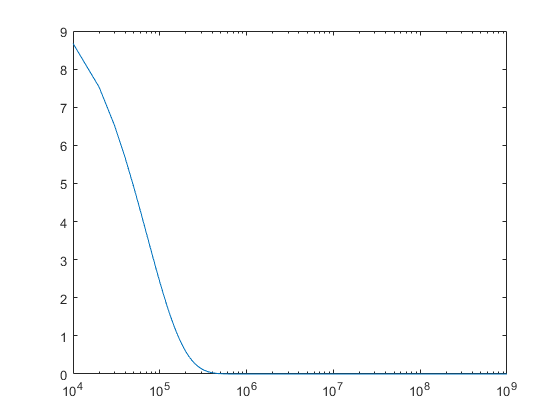

semilogx(x, p_air)

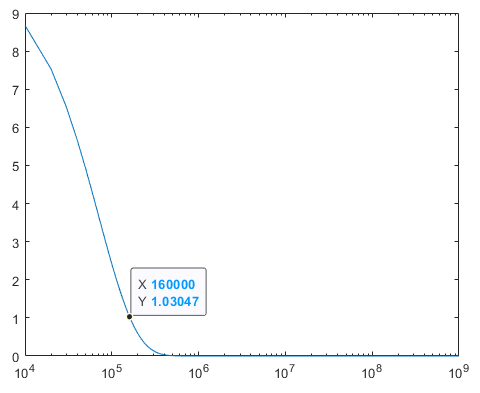

(e) In air of 10% relative humidity at 20°C?

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.2.      e)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.2.      e)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



P_0 = 10;
x = 10000:10000:1000000000;

%Air
f = 1000;       % Hz
omega = 2.*pi.*f % angular frequency (rad/s)

omega = 6.2832e+03

rho_0 = 1.21;   % density of fluid (kg/m^3) - Appendix A10 in Kinsler
c = 343;        % speed of sound (m/s) - Appendix A10 in Kinsler
k = omega./c;   % wave number
eta = 1.85e-5;  % shear viscosity coefficient (Pa*s) - Appendix A10 in Kinsler
gamma = 1.402;  % heat capacity ratio (dimensionless) - Appendix A10 in Kinsler
kappa = 0.0263; % thermal conductivity (W/m*K) - Appendix A10 in Kinsler
c_p = 1.01e3;   % specific heat (J/kg*K) - Appendix A10 in Kinsler


alpha_c_air = omega.^2./2./rho_0./c.^3.*(4/3.*eta + (gamma - 1).*kappa./c_p)

alpha_c_air = 1.4204e-05

p_air = abs(P_0.*exp(-alpha_c_air.*x).*exp(1j.*(omega.*t-k.*x)))

p_air =     8.6759    7.5271    6.5305    5.6658    4.9156    4.2647    3.7000    3.2101    2.7850    2.4163    2.0963    1.8188    1.5779    1.3690    1.1877    1.0305    0.8940    0.7757    0.6729    0.5838    0.5065    0.4395    0.3813    0.3308    0.2870    0.2490    0.2160    0.1874    0.1626    0.1411    0.1224    0.1062    0.0921    0.0799    0.0693    0.0602    0.0522    0.0453    0.0393    0.0341    0.0296    0.0257    0.0223    0.0193    0.0168    0.0145    0.0126    0.0109    0.0095    0.0082


semilogx(x, p_air)

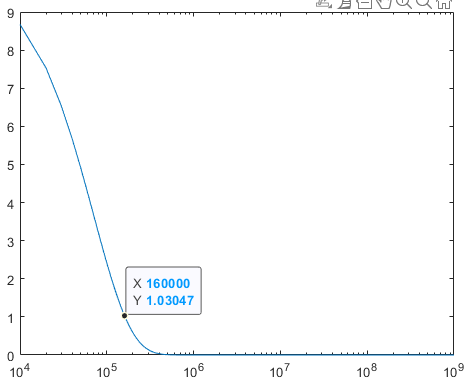

## 8.7.3C. 

(a) Plot the absorption coefficient in dB/m for seawater (35 ppt salinity) at 1 atm for  temperatures of 5°C, 15°C, and 30°C for frequencies between 100 Hz and 1000 Hz. 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.3C.     a)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.3C.     a)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



f = 100:10:1000; % Hz

% temperatures of 5°C
T = 5;
S = 35;
pH = 8;
Z = 0;
f_1 = 780.*exp(T/29)

f_1 = 926.7721

f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

alpha = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

plot(f, alpha);
hold on

% temperatures of 15°C
T = 15;
S = 35;
pH = 8;
Z = 0;
f_1 = 780.*exp(T/29)

f_1 = 1.3084e+03

f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

alpha = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

plot(f, alpha);
hold on

% temperatures of 30°C
T = 30;
S = 35;
pH = 8;
Z = 0;
f_1 = 780.*exp(T/29)

f_1 = 2.1946e+03

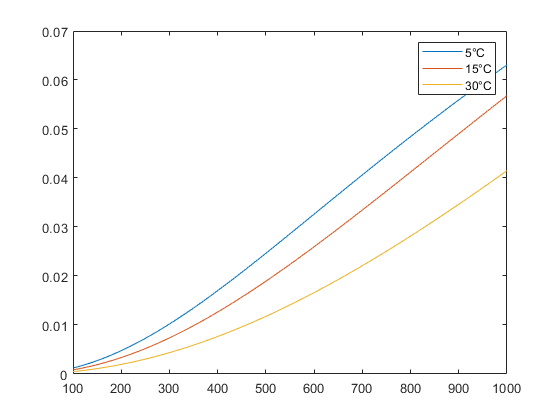

f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

alpha = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

plot(f, alpha);
hold off

legend("5°C", "15°C", "30°C")

(b)  Repeat for seawater (35 ppt salinity) at 5°C for depths of 0 m, 1000 m, and 4000 m. 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.3C.     b)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.3C.     b)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


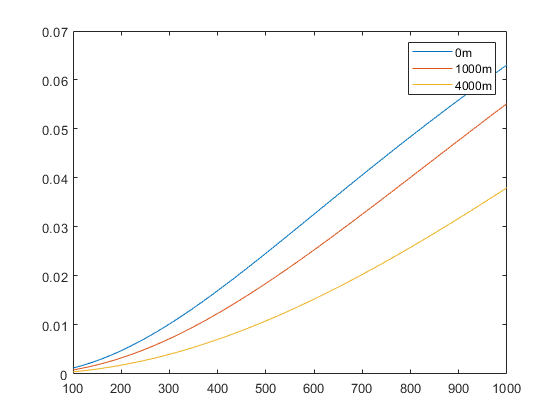


f = 100:10:1000; % Hz

% 0 m
T = 5;
S = 35;
pH = 8;
Z = 0;
f_1 = 780.*exp(T/29);
f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

a = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

plot(f, a);
hold on

% 1000m
T = 15;
S = 35;
pH = 8;
Z = 1;
f_1 = 780.*exp(T/29);
f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

a = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

plot(f, a);
hold on

% 4000m
T = 30;
S = 35;
pH = 8;
Z = 4;
f_1 = 780.*exp(T/29);
f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

a = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

plot(f, a);
hold off

legend("0m", "1000m", "4000m")

(c)  Repeat for seawater at 5°C at 0 m for salinities 0 ppt and 35 ppt

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%           8.7.3C.     c)      %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%           8.7.3C.     c)      %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


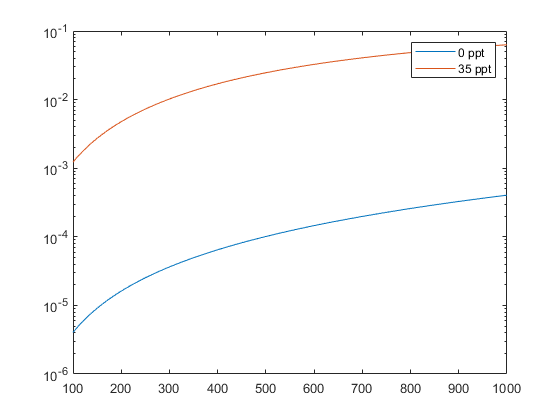


f = 100:10:1000; % Hz

% salinities 0 ppt
T = 5;
S = 0;
pH = 8;
Z = 0;
f_1 = 780.*exp(T/29);
f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

a = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

semilogy(f, a);
hold on

% salinities 35 ppt
T = 5;
S = 35;
pH = 8;
Z = 0;
f_1 = 780.*exp(T/29);
f_2 = 42000.*exp(T/18);
A = 0.083.*(S/35).*exp((T/31) - (Z/91) + (1.8.*(pH - 8)));
B = 22.*(S/35).*exp((T/14) - (Z/6));
C = (4.9e-10).*exp(-(T/26) - (Z/25));

a = ((A./(f_1^2 + f.^2)) + (B./(f_2^2 + f.^2)) + C).*f.^2;

semilogy(f, a);
hold off

legend("0 ppt", "35 ppt")